clear;clc;

% load experimental data
data_mono = xlsread('data_to_fit.xlsx', 3, 'B9:E11');
data_neu = xlsread('data_to_fit.xlsx', 3, 'B13:E15');
data_nk = xlsread('data_to_fit.xlsx', 3, 'B17:E19');
data_v = xlsread('data_to_fit.xlsx', 3, 'B21:I23');
data_t = xlsread('data_to_fit.xlsx', 3, 'B25:G27');
data_te = xlsread('data_to_fit.xlsx', 3, 'B29:G31');
data_il1b = xlsread('data_to_fit.xlsx', 3, 'B33:E35');
data_ccl2 = xlsread('data_to_fit.xlsx', 3, 'B37:E39');

data_inf_score = xlsread('data_to_fit.xlsx', 3, 'B41:C43');
    

% load immunity parameters
par_IAV = importdata('par_base.txt');
par_IAV = par_IAV.data;

% load inflammation parameters
par_infla = importdata('par_infla.txt');
par_infla = par_infla.data;

y0 = importdata('init_base.txt');
y0 = y0.data;

tmax = 1000;
tspan = 0:1:tmax;

[~, y] = ode15s(@ODE_IAV, tspan, y0, [], par_IAV);
infla = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla(i) = inflammation(y(i, 5), y(i, 6), par_infla);
end

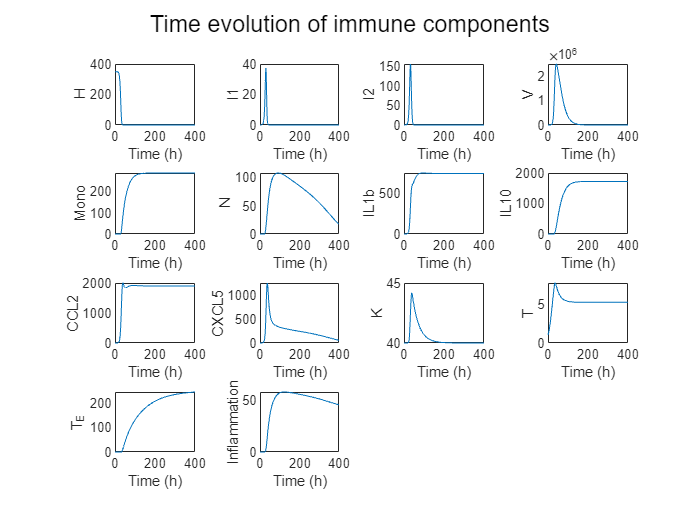


var_name = ["H", "I1", "I2", "V", "Mono", "N", "IL1b", "IL10", "CCL2", "CXCL5", "K", "T", "T_E"];
figure;
for i = 1:13
    subplot(4, 4, i);
    plot(tspan, y(:, i)); hold on;
    xlim([0 400]);
    xlabel('Time (h)');
    ylabel(var_name(i)); hold off;
end
subplot(4, 4, 14);
plot(tspan, infla);
xlim([0 400]);
xlabel('Time (h)'); ylabel('Inflammation');
sgtitle('Time evolution of immune components');

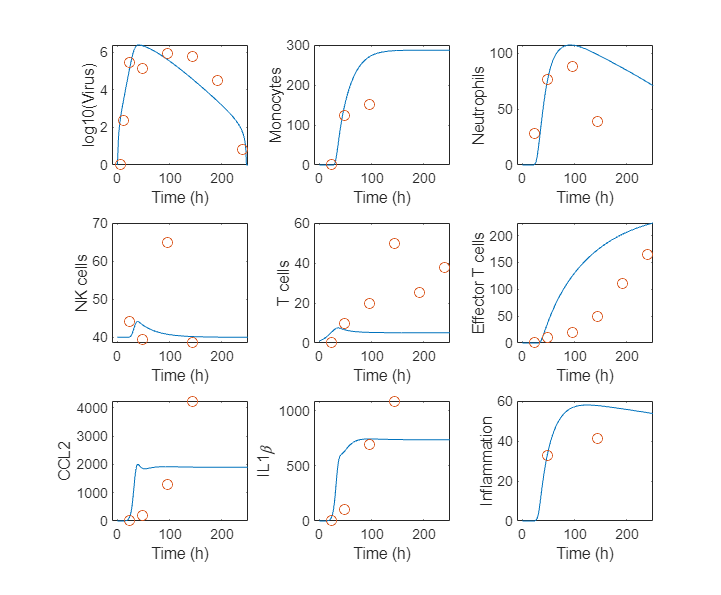

figure;
xSize = 20; X=xSize; ySize = 15;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(3, 3, 1); hold on; box on;
plot(tspan, Safe_log10(y(:, 4) - 100));
scatter(data_v(1, :), data_v(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('log10(Virus)');
hold off;

subplot(3, 3, 2); hold on; box on;
plot(tspan, y(:, 5));
scatter(data_mono(1, 1:3), data_mono(3, 1:3));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Monocytes');
hold off;

subplot(3, 3, 3); hold on; box on;
plot(tspan, y(:, 6));
scatter(data_neu(1, :), data_neu(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Neutrophils');
hold off;

subplot(3, 3, 4); hold on; box on;
plot(tspan, y(:, 11));
scatter(data_nk(1, :), data_nk(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('NK cells');
hold off;

subplot(3, 3, 5); hold on; box on;
plot(tspan, y(:, 12));
scatter(data_t(1, :), data_t(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('T cells');
hold off;

subplot(3, 3, 6); hold on; box on;
plot(tspan, y(:, 13));
scatter(data_te(1, :), data_te(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Effector T cells');
hold off;

subplot(3, 3, 7); hold on; box on;
plot(tspan, y(:, 9));
scatter(data_ccl2(1, :), data_ccl2(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('CCL2');
hold off;

subplot(3, 3, 8); hold on; box on;
plot(tspan, y(:, 7));
scatter(data_il1b(1, :), data_il1b(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('IL1\beta');
hold off;

subplot(3, 3, 9); hold on; box on;
plot(tspan, infla);
scatter(data_inf_score(1, :), data_inf_score(3, :));
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Inflammation');
hold off;

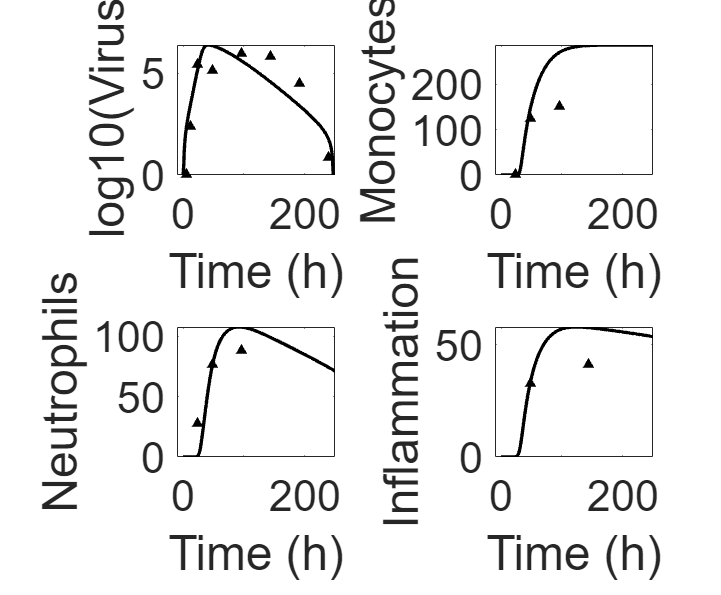

figure;
xSize = 20; X=xSize; ySize = 15;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(2, 2, 1); hold on; set(gca,'Fontsize',26); box on;
plot(tspan, Safe_log10(y(:, 4) - 100), 'k', 'LineWidth', 2); hold on;
scatter(data_v(1, :), data_v(3, :), [], 'k', 'filled', '^');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('log10(Virus)');
hold off;

subplot(2, 2, 2); hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 5), 'k', 'LineWidth', 2); hold on;
scatter(data_mono(1, 1:3), data_mono(3, 1:3), [], 'k', 'filled', '^');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Monocytes');
hold off;

subplot(2, 2, 3); hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 6), 'k', 'LineWidth', 2); hold on;
scatter(data_neu(1, 1:3), data_neu(3, 1:3), [], 'k', 'filled', '^');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Neutrophils');
hold off;

subplot(2, 2, 4); hold on; set(gca,'Fontsize',26); box on;
plot(tspan, infla, 'k', 'LineWidth', 2); hold on;
scatter(data_inf_score(1, :), data_inf_score(3, :), [], 'k', 'filled', '^');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Inflammation');
hold off;